clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = 273.15+20;
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


n = param.n;
% A = [ 0 1 ; 1 0 ];
% B = [1 ; 0];
% C = [1 15];
% Q = eye(2);

unc = [param.model.B(1,:)-param.model.B_Bar(1,:);
        param.model.B(4,:)-param.model.B_Bar(4,:)
        param.model.B(7,:)-param.model.B_Bar(7,:)
        param.model.B(10,:)-param.model.B_Bar(10,:)];
Wdelta = unc*tf([1],[1]);
WdeltaTF2SS = ss(Wdelta);
param.model.Dwd = WdeltaTF2SS.D;

Cy = blkdiag([zeros(2,1), eye(2)],[zeros(2,1), eye(2)],[zeros(2,1), eye(2)],[zeros(2,1), eye(2)]);
param.model.A = param.model.A + (.5)*eye(12);


listOfUncertainties = {[-1,1]};
m = length(listOfUncertainties);
Uncertainties = zeros(m,m,m^2);
if(m == 1)% check if the inputs share uncertainties or if they have individual uncertainties
    comb = combinations(cell2mat(listOfUncertainties(1)));
else
    comb = combinations(cell2mat(listOfUncertainties(1)),cell2mat(listOfUncertainties(2)),cell2mat(listOfUncertainties(3)),cell2mat(listOfUncertainties(4)));
end
combDouble = table2array(comb);
for i=1:length(combDouble)
    Uncertainties(:,:,i) = diag(combDouble(i,:));
end

A = param.model.A + (0)*eye(12);
B = @(i) param.model.B*(eye(4) + Uncertainties(i) * param.model.Dwd);
C = blkdiag([zeros(2,1), eye(2)],[zeros(2,1), eye(2)],[zeros(2,1), eye(2)],[zeros(2,1), eye(2)]);
Q = eye(12);
tol = 1e-2;
tol_alpha = 0;

% Step 1
yalmip('clear')
p = cell(1,param.n);
for i=1:param.n
    p{i} = sdpvar(3);
end
P = blkdiag(p{:});

constraints = [];
for k=1:length(Uncertainties)
    constraints = [constraints, [A.' * P + P * A + Q,P * B(k); B(k).' * P, eye(n)] >= 0];
end
% 
% constraints = [A.' * P + P * A + Q,P * B;
%                 B.' * P, eye(n)] >= 0;
constraints = [constraints, P >= 0];
options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints, -trace(P), options);
X(:,:,1) = value(P);
i = 1;

while 1
    % Step 2
    yalmip('clear')
    p = cell(1,param.n);
    f = cell(1,param.n);
    for j=1:param.n
        p{j} = sdpvar(3);
        f{j} = sdpvar(1,2,'full');
    end
    P = blkdiag(p{:});
    F = blkdiag(f{:});

    alpha = sdpvar(1);
    constraints = [];
    for k=1:length(Uncertainties)
        constraints = [constraints, [A.'*P + P*A - X(:,:,i)*(B(k)*B(k).')*P - P*(B(k)*B(k).')*X(:,:,i) + X(:,:,i)*(B(k)*B(k).')*X(:,:,i) - alpha*P , (B(k).'*P + F*C).';
                        (B(k).'*P + F*C), -eye(n)] <= 0];
    end
    constraints = [constraints, P >= 0];
    options = sdpsettings('verbose',0,'solver','mosek');
    sol = bisection(constraints, alpha, options);
    alpha_min = value(alpha);
    % Step 3
    if(alpha_min <= tol_alpha)
        break
    end
    % Step 4
    yalmip('clear')
    p = cell(1,param.n);
    f = cell(1,param.n);
    for j=1:param.n
        p{j} = sdpvar(3);
        f{j} = sdpvar(1,2,'full');
    end
    P = blkdiag(p{:});
    F = blkdiag(f{:});
    constraints = [];
    for k=1:length(Uncertainties)
        constraints = [constraints, [A.'*P + P*A - X(:,:,i)*(B(k)*B(k).')*P - P*(B(k)*B(k).')*X(:,:,i) + X(:,:,i)*(B(k)*B(k).')*X(:,:,i) - alpha_min*P , (B(k).'*P + F*C).';
                        (B(k).'*P + F*C), -eye(n)] <= 0];
    end
    constraints = [constraints, P >= 0];
    options = sdpsettings('verbose',0,'solver','mosek');
    sol = optimize(constraints, trace(P), options);
    P_min(:,:,i) = value(P);
    % Step 5
    if (norm(X(:,:,i) - P_min(:,:,i)) < tol)
        % Step 6
        break
    else
        i = i + 1;
        X(:,:,i) = P_min(:,:,i-1);
    end
end

Ks = zeros(1,3,param.n);
for j=1:param.n
    Ks(1,2:3,j) = F(j,2*(j-1)+1:2*j);
end
param.ctrl.Ks = Ks;
param.ctrl.Ks

ans = ans(:,:,1) =

         0    9.9078    5.5883


ans(:,:,2) =

         0    9.0535    4.4524


ans(:,:,3) =

         0    8.6961    4.5061


ans(:,:,4) =

         0    9.3524    4.7773


0.000000, 0.000000, -0.243760, -0.000000, 
-0.241769, 0.000000, -0.614213, -0.614213, 


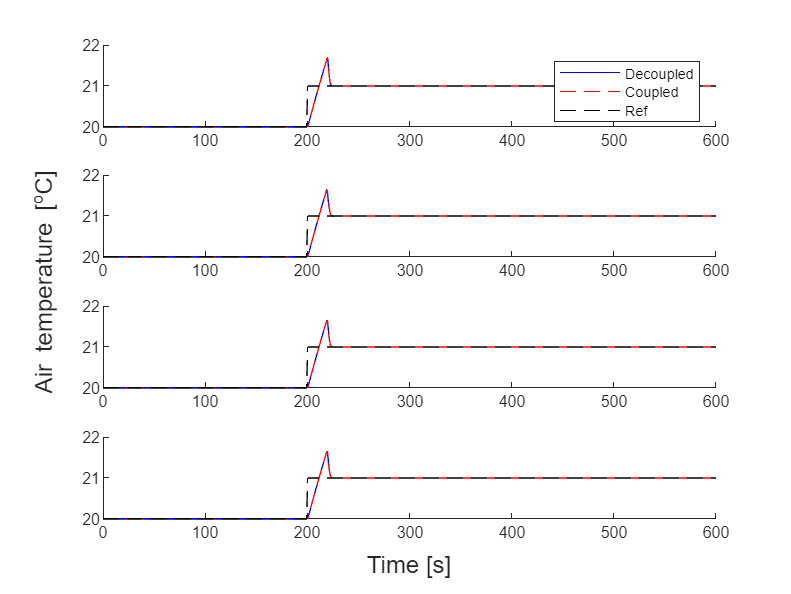

[decoupledResults,coupledResults] = util.SimulateStep(param,"Output_Feedback",0);


K = blkdiag(param.ctrl.Ks(1,2:3,1),param.ctrl.Ks(1,2:3,2),param.ctrl.Ks(1,2:3,3),param.ctrl.Ks(1,2:3,4));

s = tf('s');
M = K * C/(s * eye(12) - (param.model.A + param.model.B * K * C) )*param.model.B;
hinfnorm(M)

ans = 2.1102